# Anexo A1

Simulação da trajetória usando gerador de números aleatórios (problema 5-1.2)

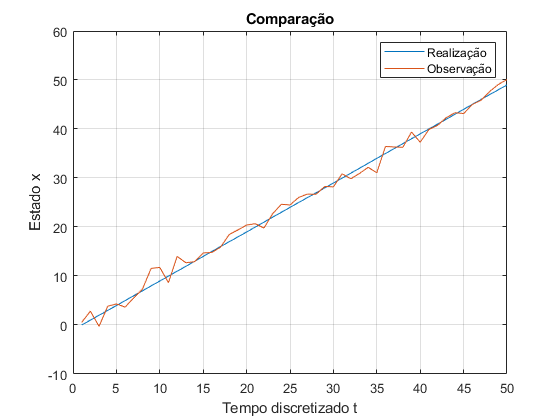

clear

f = 1;
h = 1;
q = 0.01;
r = 1;

n = 1;
k = 50;

rng('default');
v = 0 + r.*randn(n,k);
w = 0 + q.*randn(n,k);
u = zeros(n,k)+1;
x(1) = 0;   % x0
z(1) = v(1);

result(1) = x(1);
for k = 2:50
    x(k) = f*x(k-1) + u(k-1) + w(k-1); % x_{k+1}
    z(k) = h*x(k) + v(k);
end

figure;
plot(1:k, x);
hold on;
plot(1:k, z);
grid on;
title("Comparação");
xlabel("Tempo discretizado t");
ylabel("Estado x");
legend("Realização", "Observação");